% Pulse Amplitude Modulation
clc;
clear;
fs=1000;
t=1;
n=0:1/fs:t;
n=n(1:end-1);

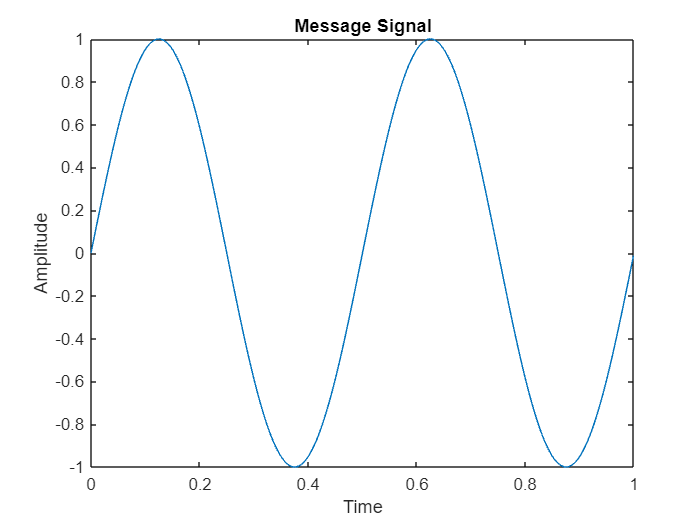

% Message Signal
fm=2;
mn=sin(2*pi*fm*n);
plot(n,mn);
xlabel("Time");
ylabel("Amplitude");
title("Message Signal")

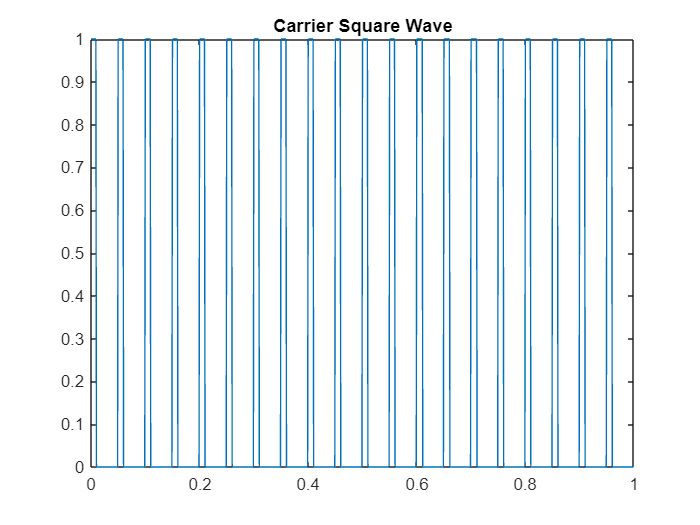

% Carrier Square Wave
fc=20;
duty=20;
sw=square(2*pi*fc*n,duty);
sw(find(sw<0))=0;
plot(n,sw);
title("Carrier Square Wave")

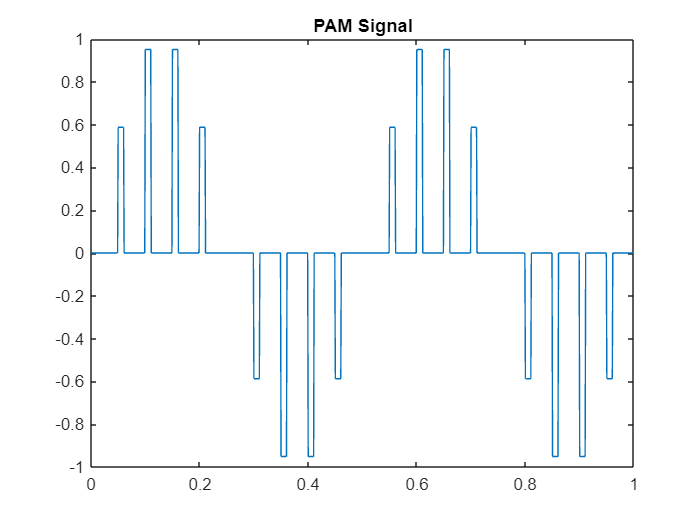

% PAM Signal
period_sample=length(n)/fc;
ind=[1:period_sample:length(n)];
on_sample=ceil(period_sample*duty/100);
pam=zeros(1,length(n));
for i=1:length(ind)
    pam(ind(i):ind(i)+on_sample)=mn(ind(i));
end
plot(n,pam);
title("PAM Signal")